Question 1.

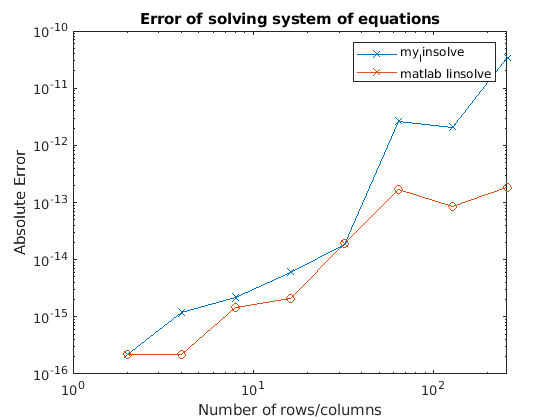

dimensions = zeros(8);
myErr = zeros(8);
myErr2 = zeros(8);
mlErr = zeros(8);
for k = 1:8 
    n = 2^k;
    dimensions(k) = n;
    rng(101);
    A = rand(n, n);
    X = rand(n, 1);
    B = A * X;
    myX = my_linsolve(A,B);
    myX2 = my_linsolve2(A,B);
    mlX = linsolve(A,B);
    myErr(k) = norm(X - myX, inf);
    myErr2(k) = norm(X - myX2, inf);
    mlErr(k) = norm(X - mlX, inf);
end
loglog(dimensions, myErr, 'x-', dimensions, mlErr, 'o-')
xlabel('Number of rows/columns')
ylabel('Absolute Error')
legend('my_linsolve', 'matlab linsolve')
title('Error of solving system of equations')

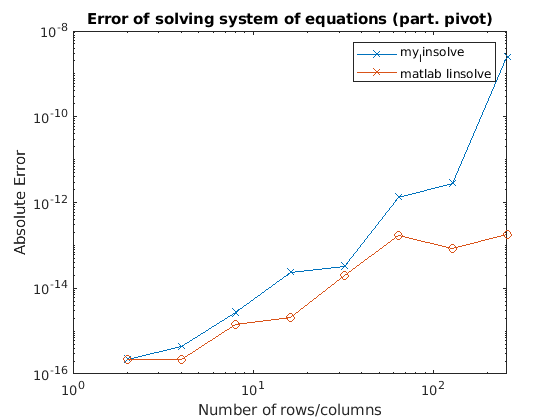


loglog(dimensions, myErr2, 'x-', dimensions, mlErr, 'o-');
xlabel('Number of rows/columns')
ylabel('Absolute Error')
legend('my_linsolve', 'matlab linsolve')
title('Error of solving system of equations (part. pivot)')

Question 2.

My partial pivoting is included in my function my_linsolve and is surrounded by comments. It uses the concept of pivoting using the row with the SMALLEST value in the current column.

function x = my_linsolve(A,b)
    n = size(A,1);
    A = [A,b];
    for j = 1:n
        for i = j+1:n
            A(i,:) = A(i,:) - A(i,j)/A(j,j)*A(j,:);
            A(i,j) = 0;
        end
    end
    
    for j = n:-1:1
        for i = 1:j-1
            A(i,:) = A(i,:) - A(i,j)/A(j,j)*A(j,:);
            A(i,j) = 0;
        end
    end
    x = A(1:n, n+1) ./ diag(A(1:n, 1:n));
end

function x = my_linsolve2(A,b)
    n = size(A,1);
    A = [A,b];
    for j = 1:n
        for i = j+1:n
            % my partial pivot is done here
            val = inf;
            index = i;
            for k = i+1:n
                if A(k,j) < val && A(k,j) ~= 0
                    val = A(k,j);
                    index = k;
                end
            end
            A([i index],:) = A([index i], :);
            % Until here
            A(i,:) = A(i,:) - A(i,j)/A(j,j)*A(j,:);
            A(i,j) = 0;
        end
    end
    
    for j = n:-1:1
        for i = 1:j-1
            A(i,:) = A(i,:) - A(i,j)/A(j,j)*A(j,:);
            A(i,j) = 0;
        end
    end
    x = A(1:n, n+1) ./ diag(A(1:n, 1:n));
end
